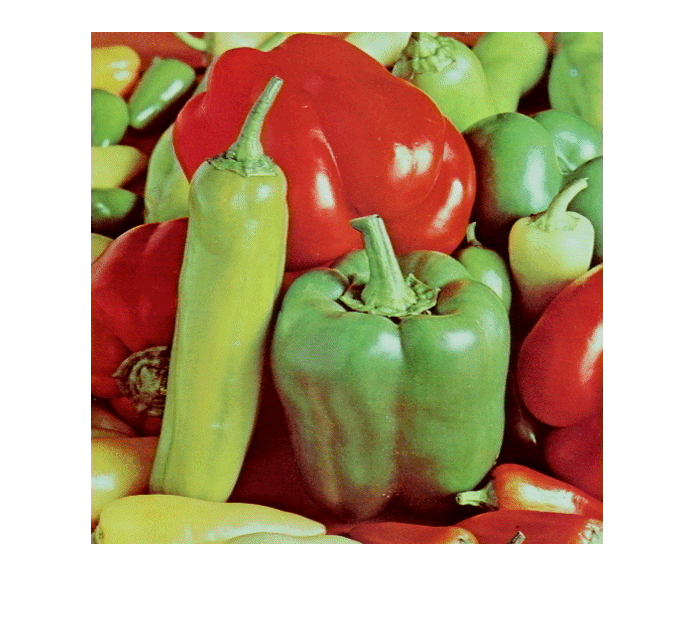

% Peppers Color is in a strange format. CData + Colormap
[peppers, map] = imread('D:\repos\Computer Vision\Lab 4\peppers_color.tif');
if ~isempty(map)
    peppers = ind2rgb(peppers(:,:,1),map);
end

% Empty 3x3 Kernel
% [a b c;
%  d e f; 
%  g h i ];
my_empty_kernel = [ 0 0 0; 0 0 0; 0 0 0 ];

% Conversion to greyscale produces a double 0->1. 
% Scale this to 0->255
% Convert to uint8 for display.
peppers_grey = uint8(rgb2gray(peppers)*255);

imshow(peppers);

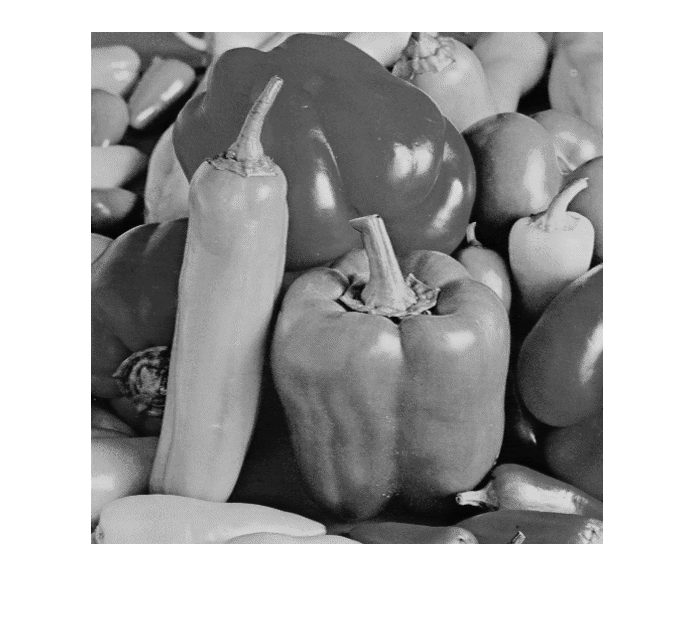

imshow(peppers_grey);

% % EXERCISE 1 & 2
% % first order derivative convolution on rgb images
% % myFilter = [0 0 0; 0 -1 1; 0 0 0]; % 1st order derivative
% % myFilter = [0 1 0; 1 -4 1; 0 1 0]; % Laplacian
% 
% [r,g,b] = imsplit(peppers); %https://uk.mathworks.com/help/images/Display-Separated-Color-Channels-of-an-RGB-Image.html
% 
% convR = conv2(r, myFilter);
% imshow(convR);
% convG = conv2(g, myFilter);
% imshow(convG);
% convB = conv2(b, myFilter);
% imshow(convB);
% 
% % Is this correct ??
% convolvedRGB = convR + convG + convB;
% imshow(convolvedRGB);
% 
% convolvedGrey = conv2(peppers_grey, myFilter);
% imshow(convolvedGrey);
% 
% imshow(r);
% imshow(g);
% imshow(b);
% 

% % EXERCISE 3
% % Convert rgb to hsv and convolve the 3 channels
% peppersHsv = rgb2hsv(peppers);
% imshow(peppers);
% title("HSV Peppers");
% 
% [h,s,v] = imsplit(peppersHsv);
% 
% imshow(h);
% title("HSV (H) Peppers");
% imshow(s);
% title("HSV (S) Peppers");
% imshow(v);
% title("HSV (V) Peppers");
% 
% cH = conv2(h, myFilter);
% imshow(cH);
% title("Conv2 HSV (H) Peppers");
% cS = conv2(s, myFilter);
% imshow(cS);
% title("Conv2 HSV (S) Peppers");
% cV = conv2(v, myFilter);
% imshow(cV);
% title("Conv2 HSV (V) Peppers");
% 
% hsvConv = cH + cS + cV;
% imshow(hsvConv);
% title("H+S+C conv");

% % EXERCISE 4
% % Produce same convolution with a Laplacian filter and observe effect on
% % noise...
% % myFilter = [0 1 0; 1 -4 1; 0 1 0]; % Laplacian
% % More detail but, consquently, more noise.

% % EXERCISE 5
% % Using the built-in Canny Edge detector, extract edges from the standard set of
% % images (cameraman, etc). How do these edges compare with the previous method/steps?
% % Do the edges ‘localise’ well? I.e Do they align with the true edge in the original input image,
% % or are they slightly off? Hint: You can overlap/blend the edge image over your input image
% % using imfuse.

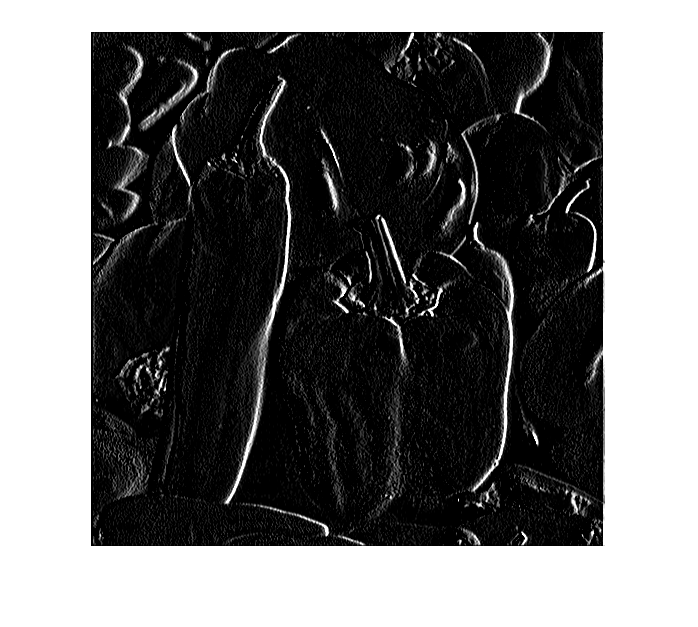

%  EXTENSION EXERCISE 1
% 1. Produce/Create a Laplacian filter/kernel which captures the diagonal running edges.
% Consider what the second derivative would be along those axes, and how we
% combined the horizontal and vertical components to make the single filter. What have
% the filters we’ve used so far summed up to? Is this important?

sobel = [-1 0 1; -2 0 2; -1 0 1]; % 1st Deriv
lapFilt = [0 1 0; 1 -4 1; 0 1 0]; % Laplacian
lapDiag = [1 0 1; 0 -4 0; 1 0 1]; % Correct?

[r,g,b] = imsplit(peppers); %https://uk.mathworks.com/help/images/Display-Separated-Color-Channels-of-an-RGB-Image.html

sobelImg = conv2(g, sobel);
imshow(sobelImg);

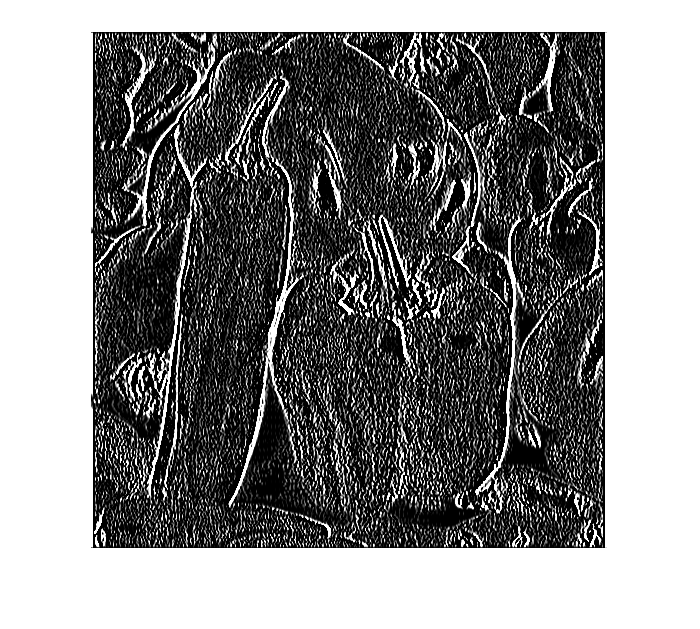


secSobel = conv2(sobelImg, sobel);
imshow(secSobel);

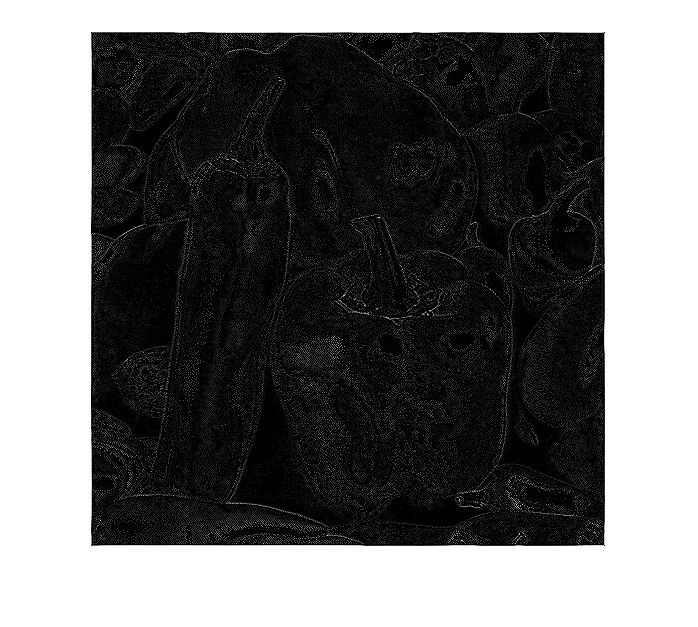


lapFiltImg = conv2(g, lapFilt);
imshow(lapFiltImg);

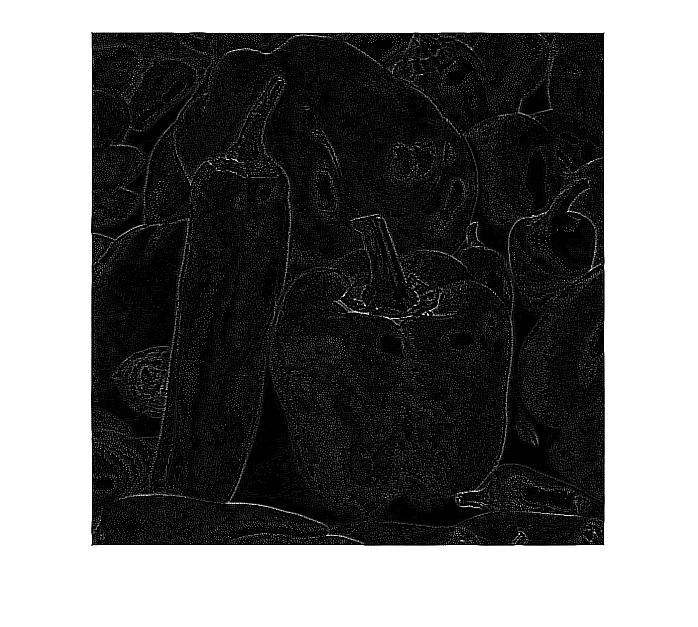


diagFiltImg = conv2(g, lapDiag);
imshow(diagFiltImg);

% EXTENSION EXERCISE 2
% Write your own Unsharp sharpening function. For the blur stage of the
% algorithm, approximate a 2D Gaussian Distribution a kernel, with parameters for the mean
% and the sigma. Additionally, your function should allow, as input, the size of kernel to be
% used.

% What does "approximate a 2d gaussian distribution kernel" mean?
blurred = convn(peppers, ones(3,3)/9, 'same');
unsharped = peppers + (peppers - blurred);
imshow(peppers);

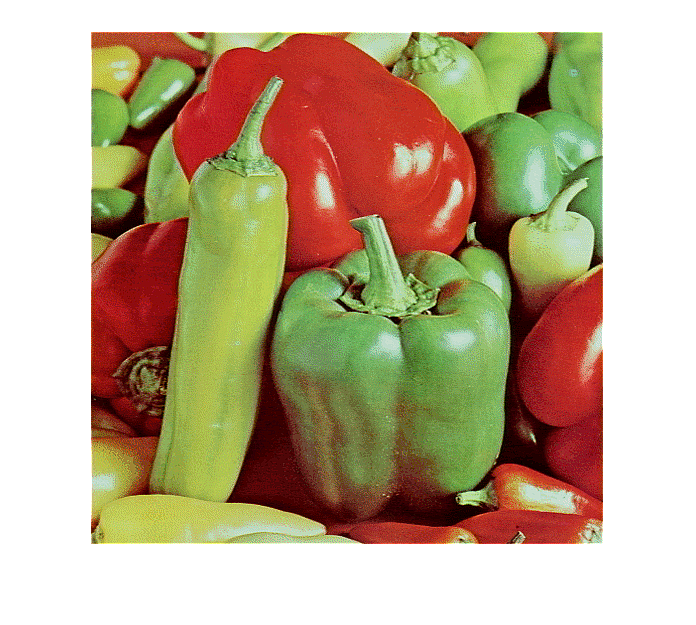

imshow(unsharped);